# Actividad #8

**Almacenamiento, Carga y Visualización Dinámica de Datasets en Formato CSV usando MATLAB**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

## Descripción:

## Objetivos:

- **Generar señales senoidales con parámetros personalizables** de frecuencia, amplitud y fase.

- **Asignar marcas de tiempo con precisión milisegundos** para simular un entorno de adquisición de datos.

- **Crear y guardar datasets en formato CSV** utilizando tablas en MATLAB.

- **Leer archivos CSV y convertirlos en tablas manipulables**, permitiendo la reutilización de datos.

- **Visualizar y analizar las señales cargadas** para validar el proceso completo de exportación e importación.

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

## Desarrollo de la Actividad

#### **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window
addpath(genpath('./src'));

#### **Paso 2: Crear un codigo basico**

% Parámetros
f = 2;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



T = 10;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 20;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal
% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs)';
y2 = senal_senoidal(f,A2,fase2,T,fs)';

simulationTime = 1×201 duration array
      0 sec   0.05 sec    0.1 sec   0.15 sec    0.2 sec   0.25 sec    0.3 sec   0.35 sec    0.4 sec   0.45 sec    0.5 sec   0.55 sec    0.6 sec   0.65 sec    0.7 sec   0.75 sec    0.8 sec   0.85 sec    0.9 sec   0.95 sec      1 sec   1.05 sec    1.1 sec   1.15 sec    1.2 sec   1.25 sec    1.3 sec   1.35 sec    1.4 sec   1.45 sec    1.5 sec   1.55 sec    1.6 sec   1.65 sec    1.7 sec   1.75 sec    1.8 sec   1.85 sec    1.9 sec   1.95 sec      2 sec   2.05 sec    2.1 sec   2.15 sec    2.2 sec   2.25 sec    2.3 sec   2.35 sec    2.4 sec   2.45 sec    2.5 sec   2.55 sec    2.6 sec   2.65 sec    2.7 sec   2.75 sec    2.8 sec   2.85 sec    2.9 sec   2.95 sec      3 sec   3.05 sec    3.1 sec   3.15 sec    3.2 sec   3.25 sec    3.3 sec   3.35 sec    3.4 sec   3.45 sec    3.5 sec   3.55 sec    3.6 sec   3.65 sec    3.7 sec   3.75 sec    3.8 sec   3.85 sec    3.9 sec   3.95 sec      4 sec   4.05 sec    4.1 sec   4.15 sec    4.2 sec   4.25 sec    4.3 sec   4.

y3 = y1 + y2;

startTime = datetime
   14-Jun-2025 08:22:38.197


y4 = y1 - y2;

timeStamp = 201×1 datetime array
   14-Jun-2025 08:22:38.197
   14-Jun-2025 08:22:38.247
   14-Jun-2025 08:22:38.297
   14-Jun-2025 08:22:38.347
   14-Jun-2025 08:22:38.397
   14-Jun-2025 08:22:38.447
   14-Jun-2025 08:22:38.497
   14-Jun-2025 08:22:38.547
   14-Jun-2025 08:22:38.597
   14-Jun-2025 08:22:38.647
   14-Jun-2025 08:22:38.697
   14-Jun-2025 08:22:38.747
   14-Jun-2025 08:22:38.797
   14-Jun-2025 08:22:38.847
   14-Jun-2025 08:22:38.897
   14-Jun-2025 08:22:38.947
   14-Jun-2025 08:22:38.997
   14-Jun-2025 08:22:39.047
   14-Jun-2025 08:22:39.097
   14-Jun-2025 08:22:39.147
   14-Jun-2025 08:22:39.197
   14-Jun-2025 08:22:39.247
   14-Jun-2025 08:22:39.297
   14-Jun-2025 08:22:39.347
   14-Jun-2025 08:22:39.397
   14-Jun-2025 08:22:39.447
   14-Jun-2025 08:22:39.497
   14-Jun-2025 08:22:39.547
   14-Jun-2025 08:22:39.597
   14-Jun-2025 08:22:39.647


#### **Paso 3: TimeStamp (dd-MMM-yyyy HH:mm:ss.SSS)**

simulationTime = seconds(0:1/fs:T)

ans = 'dd-MMM-yyyy HH:mm:ss.SSS'

%setear formto de tiempo en milisegundos 

ans =    201     1


startTime = datetime('now', 'Format', 'dd-MMM-yyyy HH:mm:ss.SSS')
timeStamp = (startTime + simulationTime)'
timeStamp.Format
size(timeStamp) %filas, columnas

#### **Paso 4: Mostrar resultados con plot**

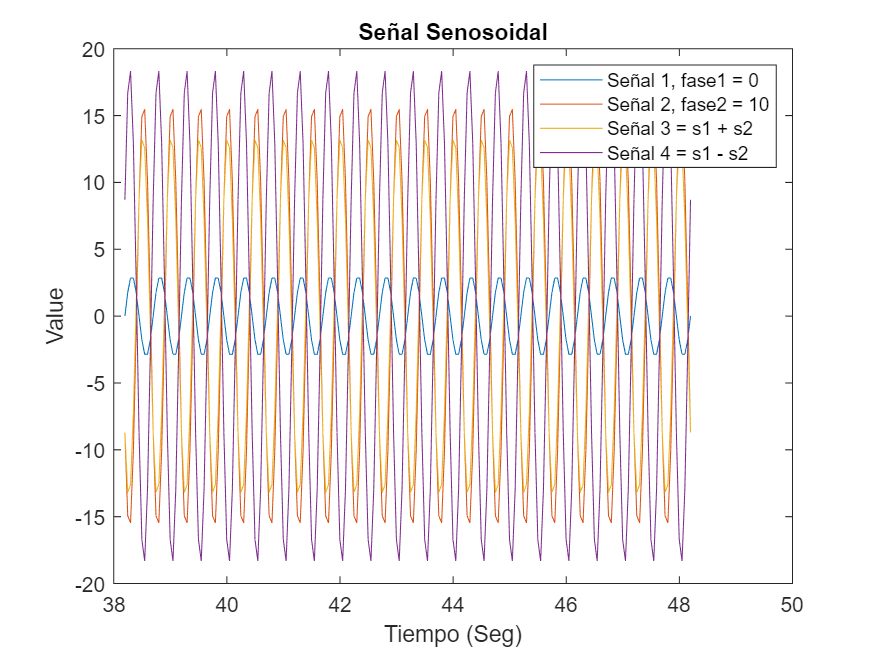

figure
plot(timeStamp.Second,y1) %Señal 1
hold on
plot(timeStamp.Second,y2) %Señal 2
plot(timeStamp.Second,y3) %Señal 3
plot(timeStamp.Second,y4) %Señal 4
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")

legend("Señal 1, fase1 = 0", "Señal 2, fase2 = 10", "Señal 3 = s1 + s2"...
    , "Señal 4 = s1 - s2")
hold off

#### **Paso 5: crear dataset usando tablas**

%cell array

VariableNames = 1×5 cell array
    {'TimeStamp'}    {'y1 = Sin1'}    {'y2 = Sin2'}    {'Y3 = y1 + y2'}    {'Y4 = y1 - y2'}


VariableNames = {'TimeStamp', 'y1 = Sin1', 'y2 = Sin2', 'Y3 = y1 + y2'...
    , 'Y4 = y1 - y2'}

dataset = 201×5 table
           TimeStamp            y1 = Sin1    y2 = Sin2    Y3 = y1 + y2    Y4 = y1 - y2
    ________________________    _________    _________    ____________    ____________

    14-Jun-2025 08:22:38.197           0      -8.7043        -8.7043         8.7043   
    14-Jun-2025 08:22:38.247      1.7634      -14.933         -13.17         16.696   
    14-Jun-2025 08:22:38.297      2.8532      -15.458        -12.605         18.311   
    14-Jun-2025 08:22:38.347      2.8532      -10.078        -7.2251         12.931   
    14-Jun-2025 08:22:38.397      1.7634     -0.84915        0.91421         2.6125   
    14-Jun-2025 08:22:38.447           0       8.7043         8.7043        -8.7043   
    14-Jun-2025 08:22:38.497     -1.7634       14.933          13.17        -16.696   
    14-Jun-2025 08:22:38

% Para la tabla el timeStamp debe ser una columna
dataset = table(timeStamp, y1, y2, y3, y4, 'VariableNames',VariableNames)

ans = 1×5 cell array
    {'TimeStamp'}    {'y1 = Sin1'}    {'y2 = Sin2'}    {'Y3 = y1 + y2'}    {'Y4 = y1 - y2'}


%Nombres de las variables
dataset.Properties.VariableNames

ans = 5

%cuantas columnas tiene el dataset
length(dataset.Properties.VariableNames)

ans = 201

%cuantas filas tiene el dataset
height(dataset) % pata Table no funcion el length

ans = 201

%cuantas filas tiene el dataset
size(dataset,1) % 1 para filas

ans = 5

%cuantas columnas tiene el dataset
size(dataset,2) % 2 para columnas

#### Paso 6: Guardar los carchivos csv en el computador

filename = 'dataset.csv';
fSave_dataset(filename,dataset)
%Limpiar workspace
clear

#### Paso 7: Leer archivos csv y retornar una tabla

rawData = fLoad_dataset('dataset.csv');

%muestra las x primera columnas
disp(rawData(1:10,:));

           TimeStamp            y1_Sin1    y2_Sin2     Y3_Y1_Y2    Y4_Y1_Y2
    ________________________    _______    ________    ________    ________

    14-Jun-2025 08:22:38.197          0     -8.7043     -8.7043     8.7043 
    14-Jun-2025 08:22:38.247     1.7634     -14.933      -13.17     16.696 
    14-Jun-2025 08:22:38.297     2.8532     -15.458     -12.605     18.311 
    14-Jun-2025 08:22:38.347     2.8532     -10.078     -7.2251     12.931 
    14-Jun-2025 08:22:38.397     1.7634    -0.84915     0.91421     2.6125 
    14-Jun-2025 08:22:38.447          0      8.7043      8.7043    -8.7043 
    14-Jun-2025 08:22:38.497    -1.7634      14.933       13.17    -16.696 
    14-Jun-2025 08:22:38.547    -2.8532      15.458      12.605    -18.311 
    14-Jun-2025 08:22:38.597    -2.8532      10.078      7.2251    -1

#### Paso 8: Extraer y graficar los datos cargados

rawData.Properties
t = datetime(rawData.TimeStamp);

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'TimeStamp'  'y1_Sin1'  'y2_Sin2'  'Y3_Y1_Y2'  'Y4_Y1_Y2'}
    VariableDescriptions: {'TimeStamp'  'y1 = Sin1'  'y2 = Sin2'  'Y3 = y1 + y2'  'Y4 = y1 - y2'}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


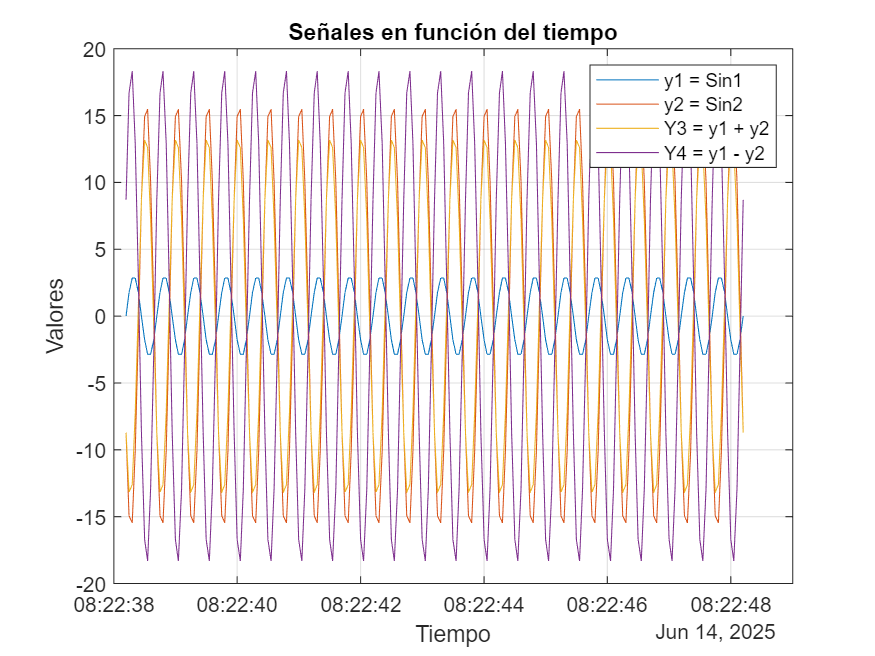

y1 = rawData.y1_Sin1;
y2 = rawData.y2_Sin2;
y3 = rawData.Y3_Y1_Y2;
y4 = rawData.Y4_Y1_Y2;

figure;
plot(t,y1); hold on;
plot(t,y2);
plot(t,y3);
plot(t,y4);

legend('y1 = Sin1', 'y2 = Sin2', 'Y3 = y1 + y2', 'Y4 = y1 - y2');
xlabel('Tiempo');
ylabel('Valores');
title('Señales en función del tiempo');
grid on;